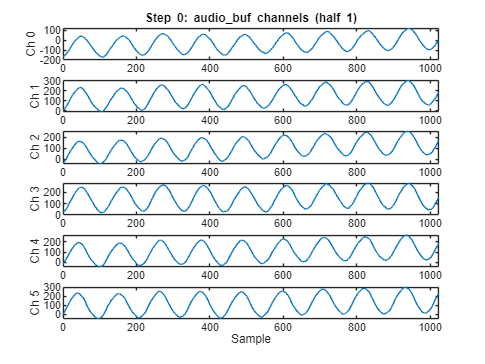

% plot_audio_buf_steps_doa.m
% Parses a raw .bin memory dump of:
%   int16_t audio_buf[2][N_CHANS][SAMPLES_PER_HALF_PER_CHAN]
% exported from STM32CubeIDE, plots each channel, then walks through
% GCC-PHAT one stage at a time (FFT -> cross-power spectrum -> PHAT
% weighting -> IFFT -> peak search), plotting the result of each stage
% instead of calling MATLAB's built-in gccphat() as one black box.
% Only processes the first half of the double buffer.
%
% Extended from the original: computes GCC-PHAT TDOA for ALL C(6,2)=15
% mic pairs (not just vs. one reference channel), feeds them into the
% geometry least-squares solver, and reports a direction of arrival.

clear; clc;

filepath = "C:\Users\Cole\Desktop\mic_array\recordings\recording1_mic4\recording1.bin";

DTYPE = 'float32';
N_HALVES = 2;
N_CHANS = 6;
SAMPLES = 1024;
Fs = 53710;
SPEED_OF_SOUND = 343; % m/s
MAX_LAG_S = 0.08/343; % 0.08 m = array diameter (2*RADIUS_M below), upper bound for ANY pair

%% Step 0: Load raw buffer and plot each channel in the time domain
fid = fopen(filepath, 'r');
if fid == -1
    error('Could not open file: %s', filepath);
end
raw = fread(fid, Inf, [DTYPE '=>double']);
fclose(fid);

expected = N_HALVES * N_CHANS * SAMPLES;
if numel(raw) ~= expected
    error('Expected %d samples, got %d. Check DTYPE/dims or file path.', expected, numel(raw));
end

buf = reshape(raw, [SAMPLES, N_CHANS, N_HALVES]); % buf(sample, chan, half)
buf_full = squeeze(buf(:,:,1)); % SAMPLES x N_CHANS, half 1 only

t = (0:size(buf_full,1)-1);

figure('Name', 'Step 0: Time-domain channels');
for ch = 1:N_CHANS
    subplot(N_CHANS, 1, ch);
    plot(t, buf_full(:,ch));
    xlim([0 SAMPLES]);
    ylabel(sprintf('Ch %d', ch-1));
    if ch == 1
        title('Step 0: audio\_buf channels (half 1)');
    end
    if ch == N_CHANS
        xlabel('Sample');
    end
end

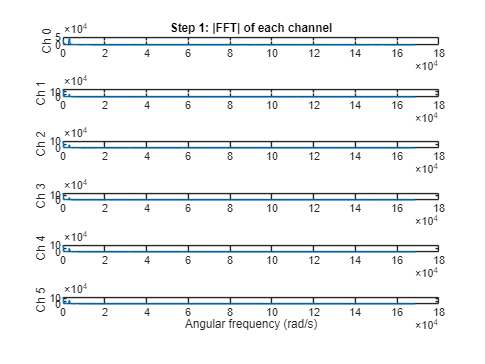


%% Step 1: FFT of every channel (shared by all pairs)
NFFT = 2^nextpow2(2*SAMPLES - 1);
freqs = Fs * (0:NFFT-1) / NFFT;
omega = 2*pi*freqs;

X = fft(buf_full, NFFT, 1); % NFFT x N_CHANS

figure('Name', 'Step 1: FFT magnitude of each channel');
for ch = 1:N_CHANS
    subplot(N_CHANS, 1, ch);
    plot(omega(1:NFFT/2), abs(X(1:NFFT/2, ch)));
    ylabel(sprintf('Ch %d', ch-1));
    if ch == 1
        title('Step 1: |FFT| of each channel');
    end
    if ch == N_CHANS
        xlabel('Angular frequency (rad/s)');
    end
end


%% Steps 2-5, generalized to every pair (i,j), i<j
% Pair order MUST match how A is built in the geometry solver below:
% for i = 1:N_MICS, for j = i+1:N_MICS
lag_samples = (-NFFT/2 : NFFT/2-1)';
lag = lag_samples / Fs;
lag_ms = lag * 1e3;
in_range = abs(lag_ms) <= MAX_LAG_S * 1000;
lag_win = lag(in_range);

pair_list = zeros(0, 2);
tdoa_pairs_s = [];

epsilon = eps;
for i = 1:N_CHANS
    for j = i+1:N_CHANS
        Gxy = X(:, i) .* conj(X(:, j));

        % PHAT-beta weighting
        Gxy_phat = Gxy ./ (abs(Gxy) .^ 0.6 + epsilon);

        cc_full = real(ifft(Gxy_phat, NFFT, 1));
        cc = fftshift(cc_full, 1);

        cc_win = cc(in_range);
        [~, idx] = max(cc_win);
        tau_ij = lag_win(idx); % seconds, delay of ch i relative to ch j

        pair_list(end+1, :) = [i, j]; %#ok<AGROW>
        tdoa_pairs_s(end+1, 1) = tau_ij; %#ok<AGROW>
    end
end

fprintf('\nPairwise GCC-PHAT TDOA (i relative to j):\n');


Pairwise GCC-PHAT TDOA (i relative to j):


for k = 1:size(pair_list, 1)
    fprintf('  (%d,%d): %+.3f samples (%+.3f ms)\n', ...
        pair_list(k,1)-1, pair_list(k,2)-1, tdoa_pairs_s(k)*Fs, tdoa_pairs_s(k)*1e3);
end

  (0,1): +4.000 samples (+0.074 ms)
  (0,2): +0.000 samples (+0.000 ms)
  (0,3): +4.000 samples (+0.074 ms)
  (0,4): +4.000 samples (+0.074 ms)
  (0,5): +7.000 samples (+0.130 ms)
  (1,2): +0.000 samples (+0.000 ms)
  (1,3): +0.000 samples (+0.000 ms)
  (1,4): +0.000 samples (+0.000 ms)
  (1,5): +0.000 samples (+0.000 ms)
  (2,3): +0.000 samples (+0.000 ms)
  (2,4): +0.000 samples (+0.000 ms)
  (2,5): +0.000 samples (+0.000 ms)
  (3,4): +0.000 samples (+0.000 ms)
  (3,5): +0.000 samples (+0.000 ms)
  (4,5): +0.000 samples (+0.000 ms)



%% Geometry solver
N_MICS = 6;
RADIUS_CM = 4;
RADIUS_M = RADIUS_CM / 100;

positions = [];
for i = 1:N_MICS
    theta_deg = (i-1) * 360/N_MICS;
    positions = [positions; RADIUS_M*cosd(theta_deg) RADIUS_M*sind(theta_deg)]; % FIX: cosd/sind, not cos/sin
end

A = [];
for i = 1:N_MICS
    for j = i+1:N_MICS
        A = [A; positions(i, :) - positions(j, :)];
    end
end

M = pinv(A' * A) * A'; % left pseudoinverse of A (2 x 15)

%% Step 6: Solve for direction of arrival
% Far-field plane-wave model: arrival time at mic position p is
%   t(p) = t0 - (p . u) / c
% where u is the unit vector pointing FROM the array TOWARD the source.
% So for TDOA tau_ij = t_i - t_j = -(p_i - p_j).u / c = -(A_row_ij . u)/c,
% i.e. b = -(1/c) * A * u  =>  u = -c * pinv(A) * b = -c * M * b
b = tdoa_pairs_s; % 15 x 1, same order as A's rows

u = -SPEED_OF_SOUND * (M * b); % 2 x 1, not yet unit norm
u_norm = norm(u);
u_hat = u / u_norm;

doa_deg = atan2d(u_hat(2), u_hat(1)); % 0 deg = +x axis (mic 1's direction), CCW positive

fprintf('\nEstimated direction of arrival: %.1f deg (0 deg = mic 1 direction, CCW+)\n', doa_deg);


Estimated direction of arrival: -162.7 deg (0 deg = mic 1 direction, CCW+)


fprintf('Solved unit vector magnitude before normalization: %.3f (closer to 1 = more self-consistent fit)\n', u_norm);

Solved unit vector magnitude before normalization: 0.181 (closer to 1 = more self-consistent fit)


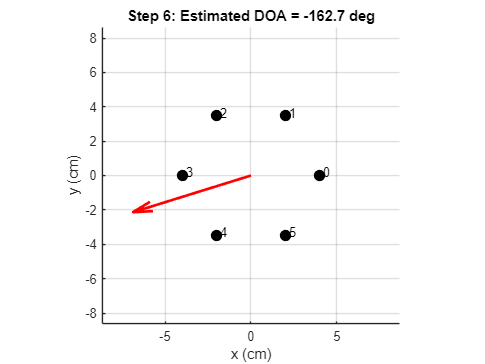


%% Plot array geometry + estimated DOA
figure('Name', 'Step 6: Mic array geometry and estimated DOA');
hold on;
plot(positions(:,1)*100, positions(:,2)*100, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
for i = 1:N_MICS
    text(positions(i,1)*100 + 0.2, positions(i,2)*100 + 0.2, sprintf('%d', i-1));
end
arrow_len = RADIUS_CM * 1.8;
quiver(0, 0, u_hat(1)*arrow_len, u_hat(2)*arrow_len, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
axis equal;
xlim([-arrow_len arrow_len]*1.2);
ylim([-arrow_len arrow_len]*1.2);
xlabel('x (cm)');
ylabel('y (cm)');
title(sprintf('Step 6: Estimated DOA = %.1f deg', doa_deg));
grid on;
hold off;